**Task A1: Define the transfer function and calculate its poles**

clc;
clear;
close all;

% Baseline transfer function
num = 16;
den = [1 4.8 16];

T2 = tf(num, den);

% Display transfer function and poles
disp('Baseline transfer function:');

Baseline transfer function:


T2


T2 =
 
         16
  ----------------
  s^2 + 4.8 s + 16
 
Continuous-time transfer function.



disp('Baseline poles:');

Baseline poles:


pole(T2)

ans =   -2.4000 + 3.2000i
  -2.4000 - 3.2000i



% Theoretical parameters
wn = 4;
zeta = 0.6;
wd = wn*sqrt(1-zeta^2);

Mp = 100*exp(-pi*zeta/sqrt(1-zeta^2));
Tp = pi/wd;
Ts_approx = 4/(zeta*wn);

fprintf('Natural frequency = %.3f rad/s\n', wn);

Natural frequency = 4.000 rad/s


fprintf('Damping ratio = %.3f\n', zeta);

Damping ratio = 0.600


fprintf('Damped frequency = %.3f rad/s\n', wd);

Damped frequency = 3.200 rad/s


fprintf('Theoretical overshoot = %.3f %%\n', Mp);

Theoretical overshoot = 9.478 %


fprintf('Theoretical peak time = %.3f s\n', Tp);

Theoretical peak time = 0.982 s


fprintf('Approx. settling time = %.3f s\n', Ts_approx);

Approx. settling time = 1.667 s


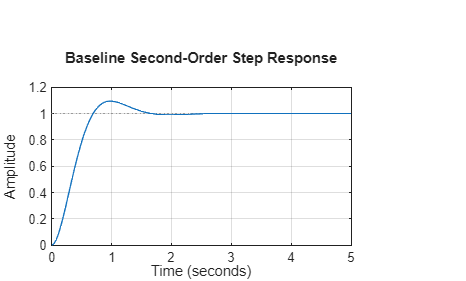


% Unit-step response
figure;
step(T2, 5);
grid on;
title('Baseline Second-Order Step Response');

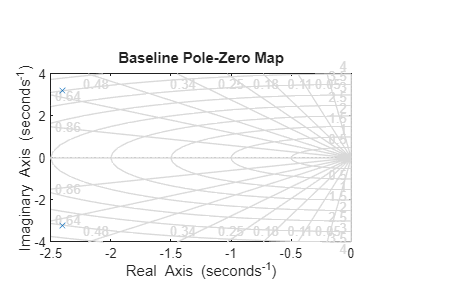


% Pole-zero map
figure;
pzmap(T2);
grid on;
title('Baseline Pole-Zero Map');


% Measured time-response metrics
info = stepinfo(T2);
disp('Baseline step response information:');

Baseline step response information:


disp(info);

         RiseTime: 0.4639
    TransientTime: 1.4859
     SettlingTime: 1.4859
      SettlingMin: 0.9083
      SettlingMax: 1.0948
        Overshoot: 9.4773
       Undershoot: 0
             Peak: 1.0948
         PeakTime: 0.9786



Task A2: Calculate theoretical time-response parameters


wn = 4;
zeta = 0.6;

% Damped natural frequency
wd = wn * sqrt(1 - zeta^2);

% Peak time
Tp = pi / wd;

% Percentage overshoot
Mp = 100 * exp(-pi*zeta/sqrt(1-zeta^2));

% Approximate settling time (2% criterion)
Ts = 4 / (zeta * wn);

fprintf('Damped Natural Frequency = %.4f rad/s\n', wd);

Damped Natural Frequency = 3.2000 rad/s


fprintf('Peak Time = %.4f seconds\n', Tp);

Peak Time = 0.9817 seconds


fprintf('Percentage Overshoot = %.4f %%\n', Mp);

Percentage Overshoot = 9.4780 %


fprintf('Approximate Settling Time = %.4f seconds\n', Ts);

Approximate Settling Time = 1.6667 seconds


**Task A3: Plot the unit-step response**

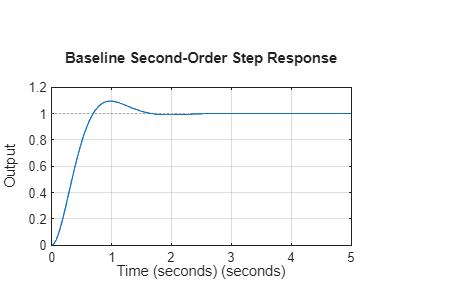

clc;
clear;
close all;

T2 = tf(16, [1 4.8 16]);

figure;
step(T2, 5);
grid on;

title('Baseline Second-Order Step Response');
xlabel('Time (seconds)');
ylabel('Output');

**Task A4: Plot the pole-zero map**

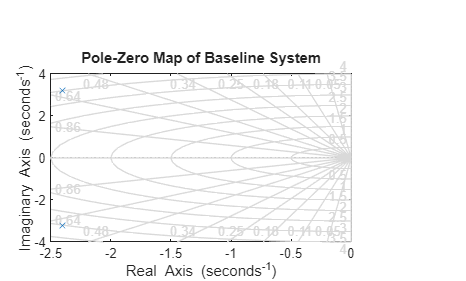

figure;
pzmap(T2);
grid on;

title('Pole-Zero Map of Baseline System');

xlabel('Real Axis');
ylabel('Imaginary Axis');

**Task A5: Measure rise time, peak time, overshoot and settling time**

T2 = tf(16, [1 4.8 16]);

info = stepinfo(T2);

disp('Baseline Time Response Information:');

Baseline Time Response Information:


disp(info);

         RiseTime: 0.4639
    TransientTime: 1.4859
     SettlingTime: 1.4859
      SettlingMin: 0.9083
      SettlingMax: 1.0948
        Overshoot: 9.4773
       Undershoot: 0
             Peak: 1.0948
         PeakTime: 0.9786




fprintf('Rise Time = %.4f s\n', info.RiseTime);

Rise Time = 0.4639 s


fprintf('Peak Time = %.4f s\n', info.PeakTime);

Peak Time = 0.9786 s


fprintf('Overshoot = %.4f %%\n', info.Overshoot);

Overshoot = 9.4773 %


fprintf('Settling Time = %.4f s\n', info.SettlingTime);

Settling Time = 1.4859 s


**Task A6: Investigate two alternative second-order designs**

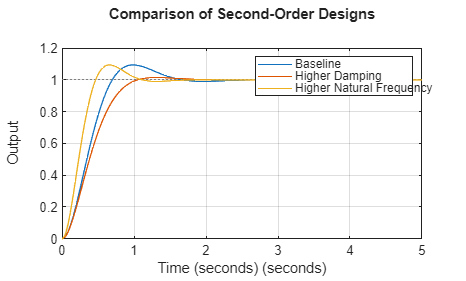

clc;
clear;
close all;

% Baseline: wn = 4, zeta = 0.6
Tbase = tf(16, [1 4.8 16]);

% Alternative 1: wn = 4, zeta = 0.8
wn1 = 4;
zeta1 = 0.8;
Talt1 = tf(wn1^2, ...
    [1 2*zeta1*wn1 wn1^2]);

% Alternative 2: wn = 6, zeta = 0.6
wn2 = 6;
zeta2 = 0.6;
Talt2 = tf(wn2^2, ...
    [1 2*zeta2*wn2 wn2^2]);

% Compare responses
figure;
step(Tbase, Talt1, Talt2, 5);
grid on;

legend('Baseline', 'Higher Damping', ...
       'Higher Natural Frequency');

title('Comparison of Second-Order Designs');
xlabel('Time (seconds)');
ylabel('Output');


% Compare metrics
disp('Baseline:');

Baseline:


disp(stepinfo(Tbase));

         RiseTime: 0.4639
    TransientTime: 1.4859
     SettlingTime: 1.4859
      SettlingMin: 0.9083
      SettlingMax: 1.0948
        Overshoot: 9.4773
       Undershoot: 0
             Peak: 1.0948
         PeakTime: 0.9786




disp('Higher Damping:');

Higher Damping:


disp(stepinfo(Talt1));

         RiseTime: 0.6170
    TransientTime: 0.9391
     SettlingTime: 0.9391
      SettlingMin: 0.9018
      SettlingMax: 1.0152
        Overshoot: 1.5165
       Undershoot: 0
             Peak: 1.0152
         PeakTime: 1.3096




disp('Higher Natural Frequency:');

Higher Natural Frequency:


disp(stepinfo(Talt2));

         RiseTime: 0.3093
    TransientTime: 0.9906
     SettlingTime: 0.9906
      SettlingMin: 0.9083
      SettlingMax: 1.0948
        Overshoot: 9.4773
       Undershoot: 0
             Peak: 1.0948
         PeakTime: 0.6524



**Task B1: Investigate three additional-pole values**

clc;
clear;
close all;

T2 = tf(16, [1 4.8 16]);

p_values = [0.5 2 15];

figure;
hold on;

% Plot baseline response
step(T2, 10);

for k = 1:length(p_values)

    p = p_values(k);

    % Add additional pole
    Tp = T2 * tf(p, [1 p]);

    step(Tp, 10);

    fprintf('\nAdditional Pole p = %.2f\n', p);

    disp('Transfer Function:');
    disp(Tp);

    disp('Poles:');
    disp(pole(Tp));

    disp('Time Response Metrics:');
    disp(stepinfo(Tp));

end


Additional Pole p = 0.50


Transfer Function:


  tf with properties:

       Numerator: {[0 0 0 8]}
     Denominator: {[1 5.3000 18.4000 8]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Poles:


  -2.4000 + 3.2000i
  -2.4000 - 3.2000i
  -0.5000 + 0.0000i



Time Response Metrics:


         RiseTime: 4.3386
    TransientTime: 8.1127
     SettlingTime: 8.1127
      SettlingMin: 0.9009
      SettlingMax: 0.9995
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9995
         PeakTime: 15.3122




Additional Pole p = 2.00


Transfer Function:


  tf with properties:

       Numerator: {[0 0 0 32]}
     Denominator: {[1 6.8000 25.6000 32]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Poles:


  -2.4000 + 3.2000i
  -2.4000 - 3.2000i
  -2.0000 + 0.0000i



Time Response Metrics:


         RiseTime: 0.9960
    TransientTime: 2.1546
     SettlingTime: 2.1546
      SettlingMin: 0.9048
      SettlingMax: 0.9996
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9996
         PeakTime: 4.1216




Additional Pole p = 15.00


Transfer Function:


  tf with properties:

       Numerator: {[0 0 0 240]}
     Denominator: {[1 19.8000 88 240]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Poles:


 -15.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Time Response Metrics:


         RiseTime: 0.4847
    TransientTime: 1.5573
     SettlingTime: 1.5573
      SettlingMin: 0.9111
      SettlingMax: 1.0907
        Overshoot: 9.0739
       Undershoot: 0
             Peak: 1.0907
         PeakTime: 1.0554



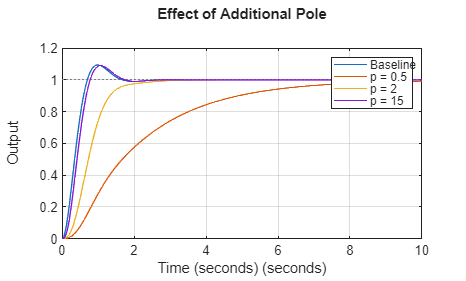


grid on;

legend('Baseline', 'p = 0.5', ...
       'p = 2', 'p = 15');

title('Effect of Additional Pole');
xlabel('Time (seconds)');
ylabel('Output');

hold off;

**Task B2: Plot the response and pole-zero map for each additional pole**

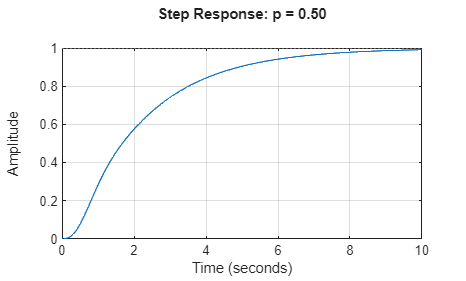

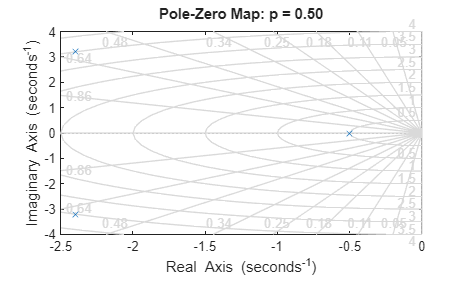


p = 0.50


Poles:


  -2.4000 + 3.2000i
  -2.4000 - 3.2000i
  -0.5000 + 0.0000i



Step Information:


         RiseTime: 4.3386
    TransientTime: 8.1127
     SettlingTime: 8.1127
      SettlingMin: 0.9009
      SettlingMax: 0.9995
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9995
         PeakTime: 15.3122



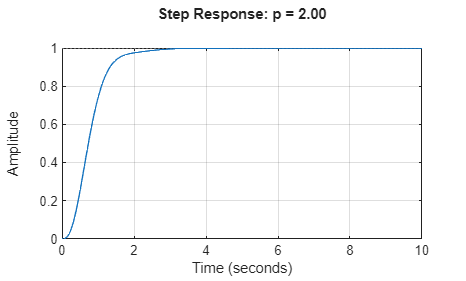

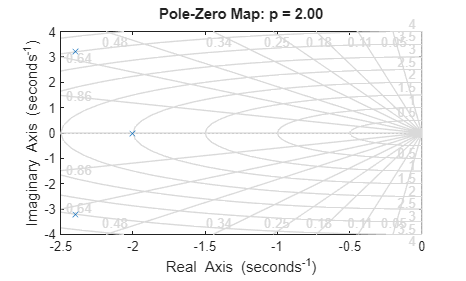


p = 2.00


Poles:


  -2.4000 + 3.2000i
  -2.4000 - 3.2000i
  -2.0000 + 0.0000i



Step Information:


         RiseTime: 0.9960
    TransientTime: 2.1546
     SettlingTime: 2.1546
      SettlingMin: 0.9048
      SettlingMax: 0.9996
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9996
         PeakTime: 4.1216



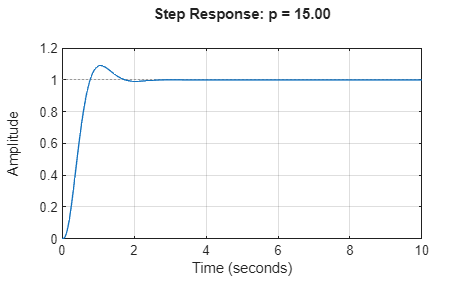

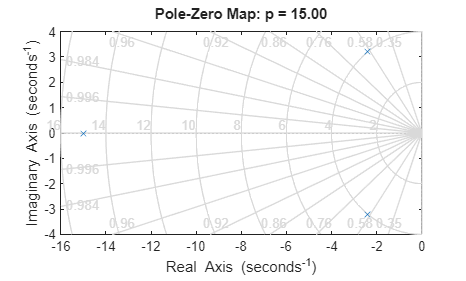


p = 15.00


Poles:


 -15.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Step Information:


         RiseTime: 0.4847
    TransientTime: 1.5573
     SettlingTime: 1.5573
      SettlingMin: 0.9111
      SettlingMax: 1.0907
        Overshoot: 9.0739
       Undershoot: 0
             Peak: 1.0907
         PeakTime: 1.0554



clc;
clear;
close all;

T2 = tf(16, [1 4.8 16]);
p_values = [0.5 2 15];

for k = 1:length(p_values)

    p = p_values(k);
    Tp = T2 * tf(p, [1 p]);

    figure;
    step(Tp, 10);
    grid on;
    title(sprintf('Step Response: p = %.2f', p));

    figure;
    pzmap(Tp);
    grid on;
    title(sprintf('Pole-Zero Map: p = %.2f', p));

    fprintf('\np = %.2f\n', p);
    disp('Poles:');
    disp(pole(Tp));

    disp('Step Information:');
    disp(stepinfo(Tp));

end

**Task C1: Investigate three additional-zero values**

clc;
clear;
close all;

T2 = tf(16, [1 4.8 16]);

z_values = [1 4 10];

figure;
hold on;

step(T2, 5);

for k = 1:length(z_values)

    z = z_values(k);

    % Additional zero and fixed pole at -20
    Tz = T2 * tf([1 z], [1 20]);

    step(Tz, 5);

    fprintf('\nAdditional Zero z = %.2f\n', z);

    disp('Transfer Function:');
    disp(Tz);

    disp('Poles:');
    disp(pole(Tz));

    disp('Zeros:');
    disp(zero(Tz));

    disp('Time Response Metrics:');
    disp(stepinfo(Tz));

end


Additional Zero z = 1.00


Transfer Function:


  tf with properties:

       Numerator: {[0 0 16 16]}
     Denominator: {[1 24.8000 112 320]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Poles:


 -20.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Zeros:


    -1



Time Response Metrics:


         RiseTime: 0.0837
    TransientTime: 1.9039
     SettlingTime: 1.9493
      SettlingMin: 0.0432
      SettlingMax: 0.1216
        Overshoot: 143.1548
       Undershoot: 0
             Peak: 0.1216
         PeakTime: 0.4191




Additional Zero z = 4.00


Transfer Function:


  tf with properties:

       Numerator: {[0 0 16 64]}
     Denominator: {[1 24.8000 112 320]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Poles:


 -20.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Zeros:


    -4



Time Response Metrics:


         RiseTime: 0.2839
    TransientTime: 1.2751
     SettlingTime: 1.2751
      SettlingMin: 0.1803
      SettlingMax: 0.2380
        Overshoot: 19.0000
       Undershoot: 0
             Peak: 0.2380
         PeakTime: 0.6908




Additional Zero z = 10.00


Transfer Function:


  tf with properties:

       Numerator: {[0 0 16 160]}
     Denominator: {[1 24.8000 112 320]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Poles:


 -20.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Zeros:


   -10



Time Response Metrics:


         RiseTime: 0.4294
    TransientTime: 1.4289
     SettlingTime: 1.4289
      SettlingMin: 0.4567
      SettlingMax: 0.5515
        Overshoot: 10.2909
       Undershoot: 0
             Peak: 0.5515
         PeakTime: 0.9210



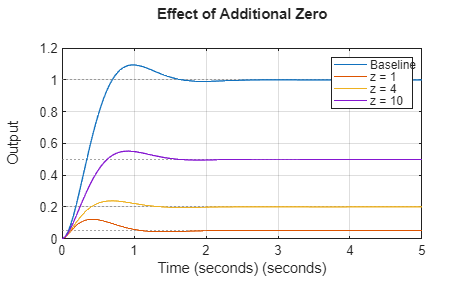


grid on;

legend('Baseline', 'z = 1', ...
       'z = 4', 'z = 10');

title('Effect of Additional Zero');
xlabel('Time (seconds)');
ylabel('Output');

hold off;

**Task C2: Normalize the additional-zero model to unity DC gain**

clc;
clear;
close all;

T2 = tf(16, [1 4.8 16]);
z_values = [1 4 10];

figure;
hold on;
step(T2, 5);

for k = 1:length(z_values)

    z = z_values(k);

    % Normalized factor: (20/z)*(s+z)/(s+20)
    Tz = T2 * tf([20/z 20], [1 20]);

    step(Tz, 5);

    fprintf('\nNormalized Zero Model: z = %.2f\n', z);
    disp('Poles:');
    disp(pole(Tz));

    disp('Zeros:');
    disp(zero(Tz));

    disp('Step Information:');
    disp(stepinfo(Tz));

end


Normalized Zero Model: z = 1.00


Poles:


 -20.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Zeros:


    -1



Step Information:


         RiseTime: 0.0837
    TransientTime: 1.9039
     SettlingTime: 1.9493
      SettlingMin: 0.8643
      SettlingMax: 2.4315
        Overshoot: 143.1548
       Undershoot: 0
             Peak: 2.4315
         PeakTime: 0.4191




Normalized Zero Model: z = 4.00


Poles:


 -20.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Zeros:


    -4



Step Information:


         RiseTime: 0.2839
    TransientTime: 1.2751
     SettlingTime: 1.2751
      SettlingMin: 0.9016
      SettlingMax: 1.1900
        Overshoot: 19.0000
       Undershoot: 0
             Peak: 1.1900
         PeakTime: 0.6908




Normalized Zero Model: z = 10.00


Poles:


 -20.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Zeros:


   -10



Step Information:


         RiseTime: 0.4294
    TransientTime: 1.4289
     SettlingTime: 1.4289
      SettlingMin: 0.9134
      SettlingMax: 1.1029
        Overshoot: 10.2909
       Undershoot: 0
             Peak: 1.1029
         PeakTime: 0.9210



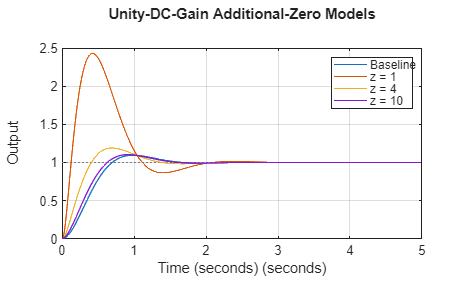


grid on;
legend('Baseline', 'z = 1', ...
       'z = 4', 'z = 10');

title('Unity-DC-Gain Additional-Zero Models');
xlabel('Time (seconds)');
ylabel('Output');

hold off;

**Task D1: Test three combinations of \(p\) and \(z\)**

clc;
clear;
close all;

T2 = tf(16, [1 4.8 16]);

p_values = [2 15 30];
z_values = [1 4 10];

figure;
hold on;
step(T2, 5);

for k = 1:length(p_values)

    p = p_values(k);
    z = z_values(k);

    % Additional pole
    Tp = tf(p, [1 p]);

    % Additional zero with fixed pole at -20
    Tz = tf([1 z], [1 20]);

    % Combined model
    Tpz = T2 * Tp * Tz;

    step(Tpz, 5);

    fprintf('\nCombined Model: p = %.2f, z = %.2f\n', p, z);

    disp('Transfer Function:');
    disp(Tpz);

    disp('Poles:');
    disp(pole(Tpz));

    disp('Zeros:');
    disp(zero(Tpz));

    disp('Step Response Metrics:');
    disp(stepinfo(Tpz));

end


Combined Model: p = 2.00, z = 1.00


Transfer Function:


  tf with properties:

       Numerator: {[0 0 0 32 32]}
     Denominator: {[1 26.8000 161.6000 544 640]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Poles:


 -20.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i
  -2.0000 + 0.0000i



Zeros:


    -1



Step Response Metrics:


         RiseTime: 0.2707
    TransientTime: 1.8505
     SettlingTime: 1.8505
      SettlingMin: 0.0479
      SettlingMax: 0.0770
        Overshoot: 54.0898
       Undershoot: 0
             Peak: 0.0770
         PeakTime: 0.8289




Combined Model: p = 15.00, z = 4.00


Transfer Function:


  tf with properties:

       Numerator: {[0 0 0 240 960]}
     Denominator: {[1 39.8000 484 2000 4800]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Poles:


 -20.0000 + 0.0000i
 -15.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Zeros:


    -4



Step Response Metrics:


         RiseTime: 0.3129
    TransientTime: 1.3489
     SettlingTime: 1.3489
      SettlingMin: 0.1817
      SettlingMax: 0.2364
        Overshoot: 18.1936
       Undershoot: 0
             Peak: 0.2364
         PeakTime: 0.7691




Combined Model: p = 30.00, z = 10.00


Transfer Function:


  tf with properties:

       Numerator: {[0 0 0 480 4800]}
     Denominator: {[1 54.8000 856 3680 9600]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Poles:


 -30.0000 + 0.0000i
 -20.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Zeros:


   -10



Step Response Metrics:


         RiseTime: 0.4350
    TransientTime: 1.4636
     SettlingTime: 1.4636
      SettlingMin: 0.4502
      SettlingMax: 0.5510
        Overshoot: 10.1945
       Undershoot: 0
             Peak: 0.5510
         PeakTime: 0.9487



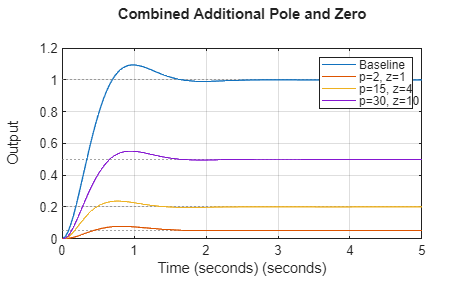


grid on;

legend('Baseline', 'p=2, z=1', ...
       'p=15, z=4', 'p=30, z=10');

title('Combined Additional Pole and Zero');
xlabel('Time (seconds)');
ylabel('Output');

hold off;

**Task D2: Combined model with unity DC gain**

clc;
clear;
close all;

T2 = tf(16, [1 4.8 16]);

p_values = [2 15 30];
z_values = [1 4 10];

figure;
hold on;
step(T2, 5);

for k = 1:length(p_values)

    p = p_values(k);
    z = z_values(k);

    Tp = tf(p, [1 p]);

    % Unity-DC-gain zero factor
    Tz = tf([20/z 20], [1 20]);

    Tpz = T2 * Tp * Tz;

    step(Tpz, 5);

    fprintf('\nCombined Model: p = %.2f, z = %.2f\n', p, z);

    disp('Poles:');
    disp(pole(Tpz));

    disp('Zeros:');
    disp(zero(Tpz));

    disp('Step Information:');
    disp(stepinfo(Tpz));

end


Combined Model: p = 2.00, z = 1.00


Poles:


 -20.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i
  -2.0000 + 0.0000i



Zeros:


    -1



Step Information:


         RiseTime: 0.2707
    TransientTime: 1.8505
     SettlingTime: 1.8505
      SettlingMin: 0.9589
      SettlingMax: 1.5409
        Overshoot: 54.0898
       Undershoot: 0
             Peak: 1.5409
         PeakTime: 0.8289




Combined Model: p = 15.00, z = 4.00


Poles:


 -20.0000 + 0.0000i
 -15.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Zeros:


    -4



Step Information:


         RiseTime: 0.3129
    TransientTime: 1.3489
     SettlingTime: 1.3489
      SettlingMin: 0.9083
      SettlingMax: 1.1819
        Overshoot: 18.1936
       Undershoot: 0
             Peak: 1.1819
         PeakTime: 0.7691




Combined Model: p = 30.00, z = 10.00


Poles:


 -30.0000 + 0.0000i
 -20.0000 + 0.0000i
  -2.4000 + 3.2000i
  -2.4000 - 3.2000i



Zeros:


   -10



Step Information:


         RiseTime: 0.4350
    TransientTime: 1.4636
     SettlingTime: 1.4636
      SettlingMin: 0.9005
      SettlingMax: 1.1019
        Overshoot: 10.1945
       Undershoot: 0
             Peak: 1.1019
         PeakTime: 0.9487



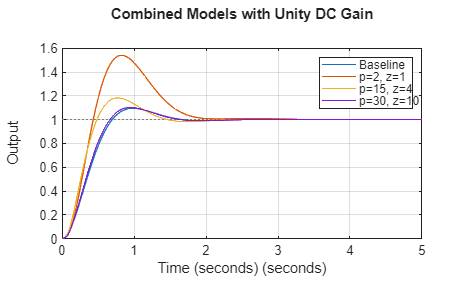


grid on;

legend('Baseline', 'p=2, z=1', ...
       'p=15, z=4', 'p=30, z=10');

title('Combined Models with Unity DC Gain');
xlabel('Time (seconds)');
ylabel('Output');

hold off;

**Final task — Compare all models and check the specifications**

clc;
clear;
close all;

T2 = tf(16, [1 4.8 16]);

models = {T2};
names = {'Baseline'};

% Additional-pole models
p_values = [0.5 2 15];

for p = p_values
    models{end+1} = T2 * tf(p, [1 p]);
    names{end+1} = sprintf('Additional pole p=%g', p);
end

% Unity-DC-gain additional-zero models
z_values = [1 4 10];

for z = z_values
    models{end+1} = T2 * tf([20/z 20], [1 20]);
    names{end+1} = sprintf('Additional zero z=%g', z);
end

% Combined models
p_values = [2 15 30];
z_values = [1 4 10];

for k = 1:length(p_values)

    p = p_values(k);
    z = z_values(k);

    Tp = tf(p, [1 p]);
    Tz = tf([20/z 20], [1 20]);

    models{end+1} = T2 * Tp * Tz;
    names{end+1} = sprintf('Combined p=%g, z=%g', p, z);
end

% Display comparison table
n = length(models);

Model = strings(n,1);
Overshoot = zeros(n,1);
SettlingTime = zeros(n,1);
SteadyStateError = zeros(n,1);
Stable = false(n,1);
SpecificationsMet = false(n,1);

for k = 1:n

    sys = models{k};
    info = stepinfo(sys);

    Model(k) = names{k};
    Overshoot(k) = info.Overshoot;
    SettlingTime(k) = info.SettlingTime;

    % Unit-step steady-state error
    finalValue = dcgain(sys);
    SteadyStateError(k) = abs(1 - finalValue);

    % Stability test
    Stable(k) = all(real(pole(sys)) < 0);

    % Check all design targets
    SpecificationsMet(k) = ...
        Stable(k) && ...
        Overshoot(k) <= 10 && ...
        SettlingTime(k) <= 2.5 && ...
        SteadyStateError(k) < 1e-6;
end

Results = table(Model, Overshoot, SettlingTime, ...
    SteadyStateError, Stable, SpecificationsMet);

disp(Results);

             Model             Overshoot    SettlingTime    SteadyStateError    Stable    SpecificationsMet
    _______________________    _________    ____________    ________________    ______    _________________

    "Baseline"                  9.4773         1.4859              0            true            true       
    "Additional pole p=0.5"          0         8.1127              0            true            false      
    "Additional pole p=2"            0         2.1546              0            true            true       
    "Additional pole p=15"      9.0739         1.5573              0            true            true       
    "Additional zero z=1"       143.15         1.9493              0            true            false      
    "Additional zero z=4"           19 